backXray=medicalImage('back view01.dcm')

backXray =   medicalImage with properties:

          Pixels: [2971×1575 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


img=extractFrame(backXray,1);

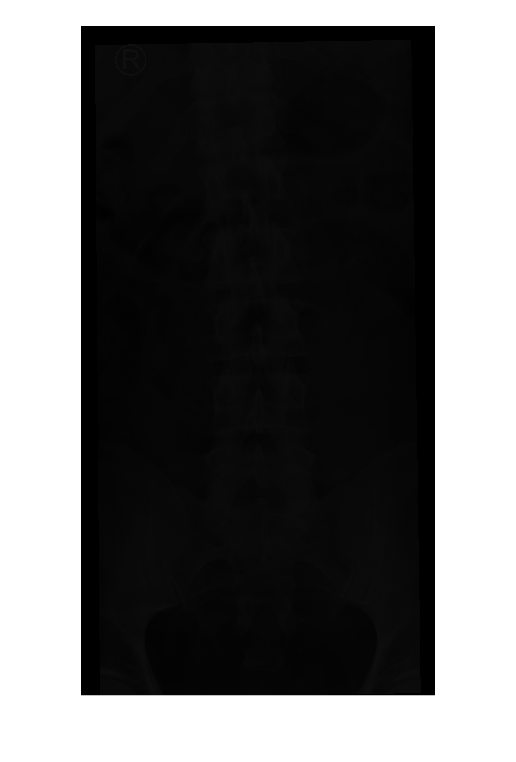

imshow(img)

minVal=backXray.WindowCenter-backXray.WindowWidth/2

minVal = 0

maxVal=backXray.WindowCenter+backXray.WindowWidth/2

maxVal = 4096

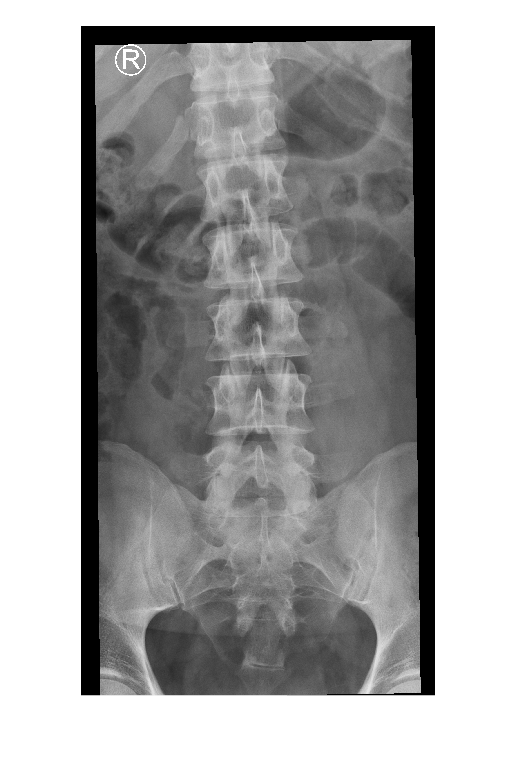

imshow(img,[minVal,maxVal])

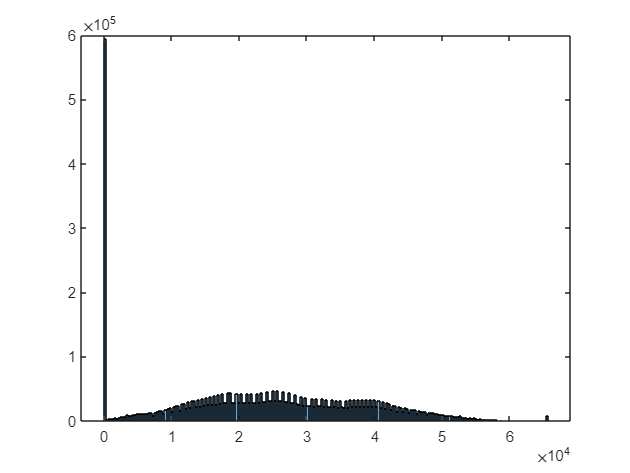

imgAdj=imadjust(img,[800 3500]/65535);
figure
histogram(imgAdj)

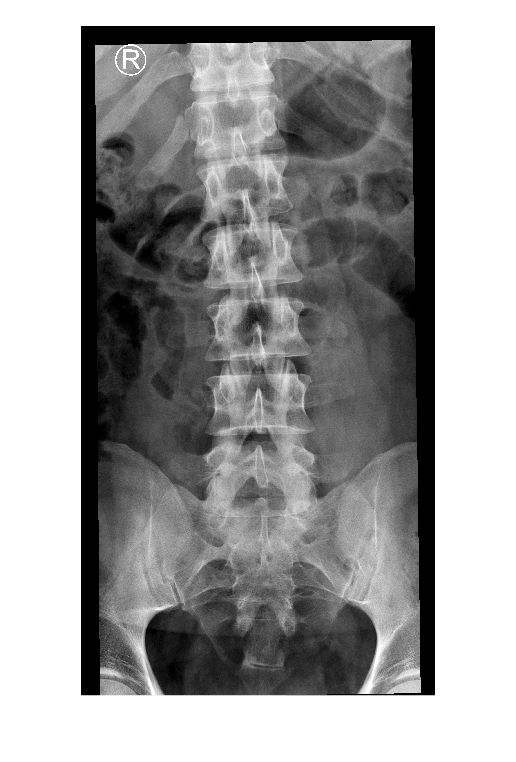

imshow(imgAdj)

backXray_2=medicalImage("back view02.dcm")

backXray_2 =   medicalImage with properties:

          Pixels: [3028×1676 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


img_2=extractFrame(backXray_2,1);

D_2_value=D_2.Value*backXray_2.PixelSpacing(1)

Dot indexing is not supported for variables of this type.

max_intensity=max(img_2(:))

max_intensity = uint16
4095

vol7T=medicalVolume("C:\Users\thamilezai\Downloads\Medical Image Processing\Data\MRI Images\T1_7T_2020")

vol7T =   medicalVolume with properties:

                 Voxels: [128×128×96 int16]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "mm"
            Orientation: "sagittal"
           VoxelSpacing: [2 2 2]
           NormalVector: [-1 0 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 96
    NumTransverseSlices: 128
           PlaneMapping: ["coronal"    "transverse"    "sagittal"]
               Modality: "MR"
          WindowCenters: [96×1 double]
           WindowWidths: [96×1 double]


v = medicalVolume("C:\Users\thamilezai\Downloads\Medical Image Processing\Data\Labeled Data\T1_3T_2018.nii")

v =   medicalVolume with properties:

                 Voxels: [192×192×128 uint8]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "mm"
            Orientation: "coronal"
           VoxelSpacing: [2.6042 2.6042 3.1000]
           NormalVector: [0 1 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 192
    NumTransverseSlices: 192
           PlaneMapping: ["sagittal"    "transverse"    "coronal"]
               Modality: "unknown"
          WindowCenters: 0
           WindowWidths: 0


uniqueLabels = unique(v.Voxels)

uniqueLabels = 3×1 uint8 column vector
   0
   1
   2


numLabels = numel(uniqueLabels)

numLabels = 3

leftHemiVoxelCount = sum(v.Voxels(:) == 1)

leftHemiVoxelCount = 28849